clc;
clear all;
close all;

SYNTHETIC DATA

%Call function to create synthetic data
[TargetMineralVolumes,mineralWF,mineralVF, ElementWF, TargetMineralWeights, Rhob] = CreateSyntheticData();

%Rhob in sample*1 format
%select elements to input to neural network
x=ElementWF(:,[1:3 5:end])';%all elements but Gd (fractions wt/wt)

%Create full input matrix which bulk density and element weight fractions
xv=[Rhob';x]; 

%Create output final mineral weight and volume fractions
twv=[TargetMineralWeights';TargetMineralVolumes'];


NEURAL NETWORK TRAINING

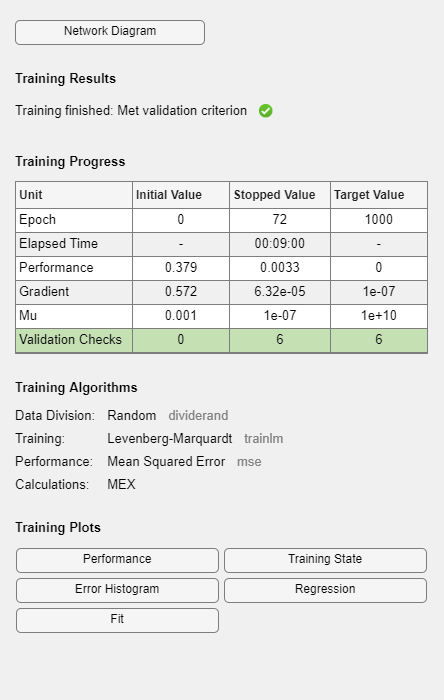

%initialise random number generator with seed 0 to ensure repeatability
rng(0)


%Neurtal Network properties

%Size
hiddenlayersize=25;

%feedforward network training function
net=fitnet(hiddenlayersize,'trainlm');

%Performance function
net.performFCN='mse';

%Sample selection method
net.divideFcn = 'dividerand';

%Output layer transfer function
net.layers{2}.transferFcn='satlin';
 
%Remove Process Functions
net.inputs{1}.processFcns={};
net.outputs{:}.processFcns={};


%Set training, testing and validation ratios
net.divideParam.trainRatio=80/100;
net.divideParam.testRatio=10/100;
net.divideParam.valRatio=10/100; 

%Set maximum epochs to avoid early training stopping
net.trainParam.epochs=1000;

%Launch training
[net, tr]=train(net,xv,twv);

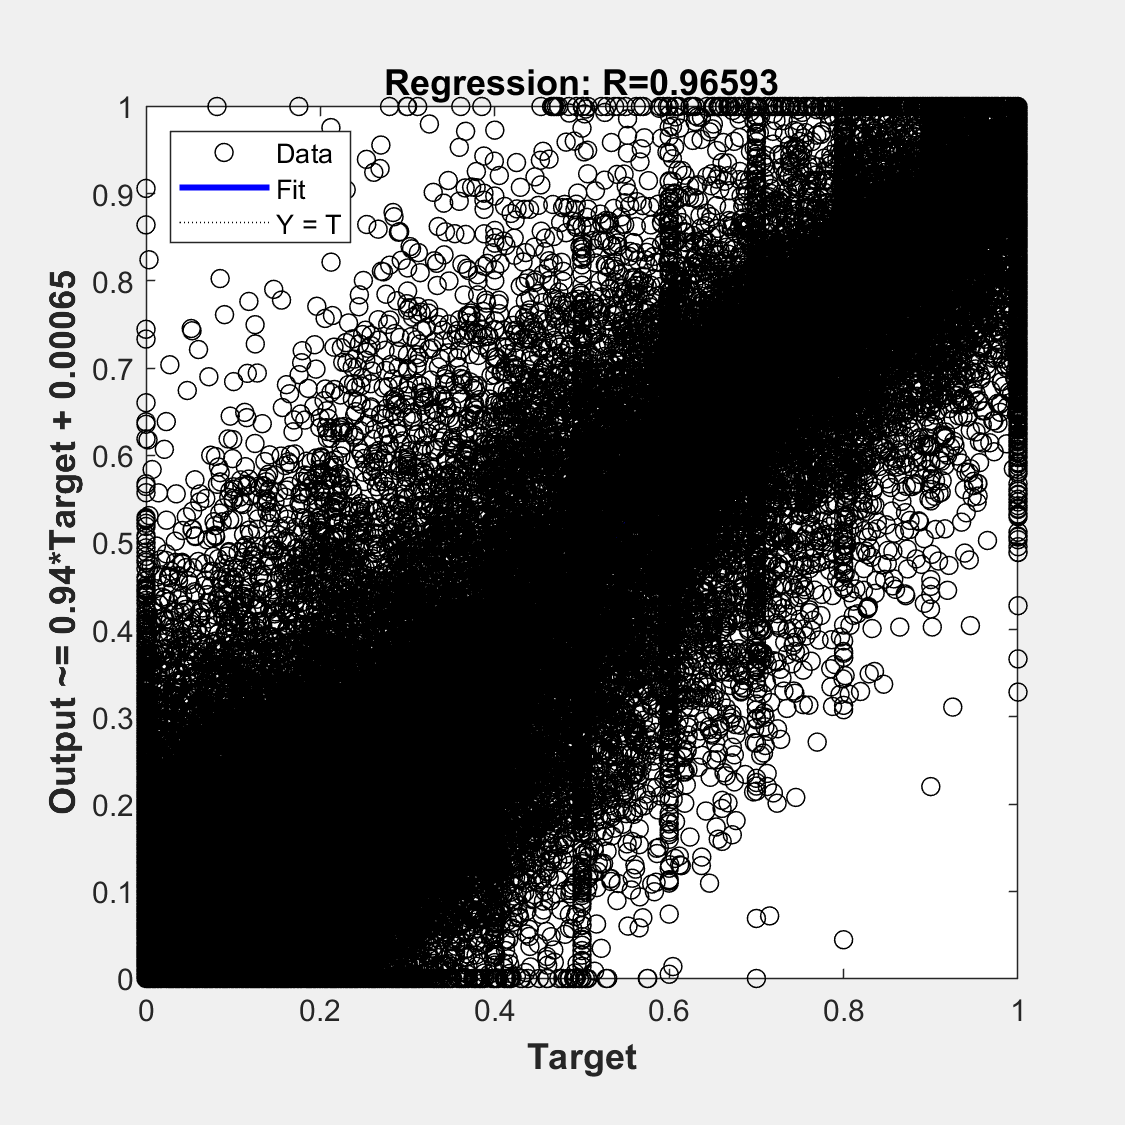


%Calculate network outputs
y=net(xv);
plotregression(twv,y,'Regression');


%Performance Calculations
errors = gsubtract(twv,y);
performance = perform(net,twv,y)

performance = 0.0033


MSEREF  = mean(var(twv',1))  % Reference MSE 

MSEREF = 0.0429

NMSE    = mse(twv-y)/MSEREF %normalised MSE

NMSE = 0.0775

Rsquare = 1 - NMSE %Rsquared

Rsquare = 0.9225


%Calculate RMSE for each mineral weight and volume
RMSE_mineral=sqrt(mean((y'-twv').^2)) 

RMSE_mineral =     0.0381    0.0372    0.0397    0.0475    0.1084    0.1140    0.0530    0.0725    0.0204    0.0249    0.0461    0.0352    0.0324    0.0336    0.0422    0.0905    0.1046    0.0392    0.0581    0.0164    0.0153    0.0259


Calculate Volume fractions corresponding to network volume fraction outputs

%Back calculate mineral weight from neural network output volumes -rhob in samp*1 format and mineral volume fractions in mineral*samp format
[mineralWt]=CalculateWeightFractions(y(12:22,:),Rhob);
